clc; clear all; close all;

img_path = fullfile('Codes','fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

RGB = imread(string(fullfile(img_path, T{52,1})));%Aquí elijes la imagen
R=RGB(:,:,1);
G=RGB(:,:,2);
B=RGB(:,:,3);
maxR=max(R(:));
maxG=max(G(:));
maxB=max(B(:)); 

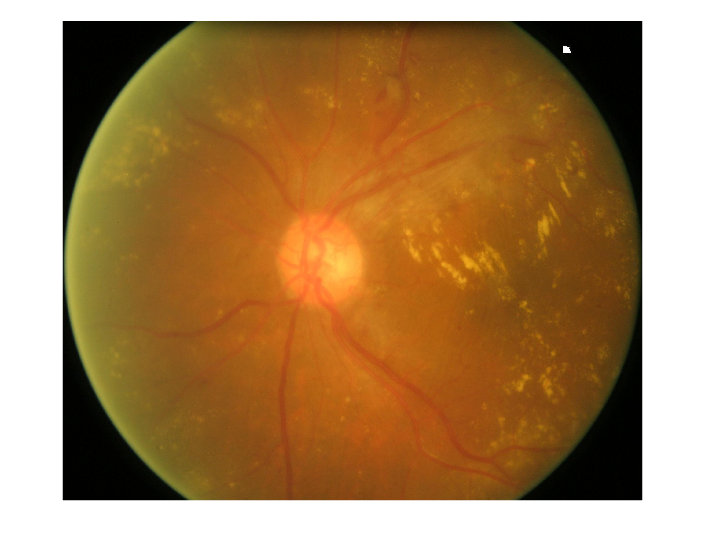

figure;
imshow((RGB));

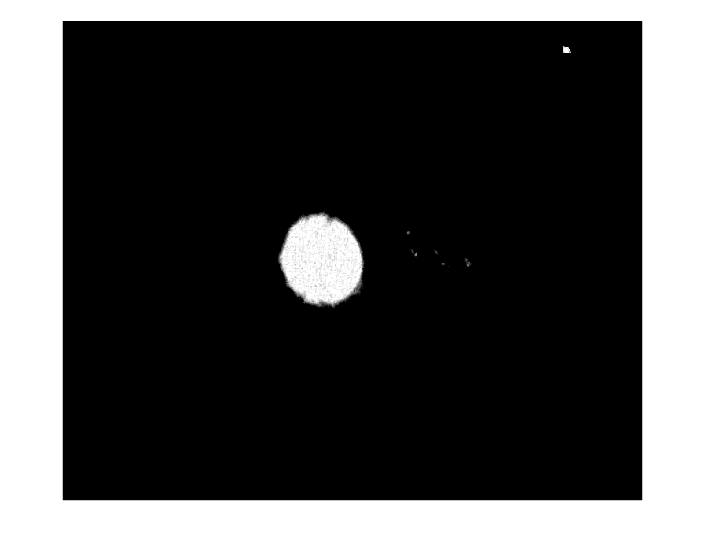

figure;
imshow(RGB(:,:,1),[0.9*maxR maxR]);

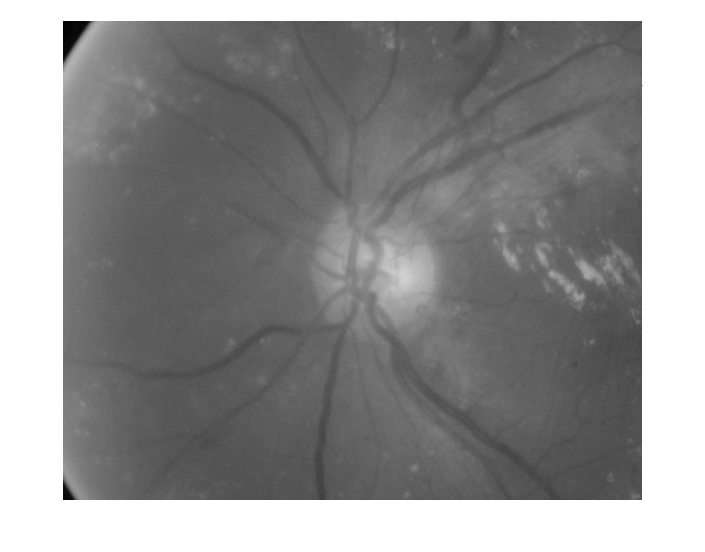

figure;
imshow(RGB(:,:,2),[0*maxG maxG]);

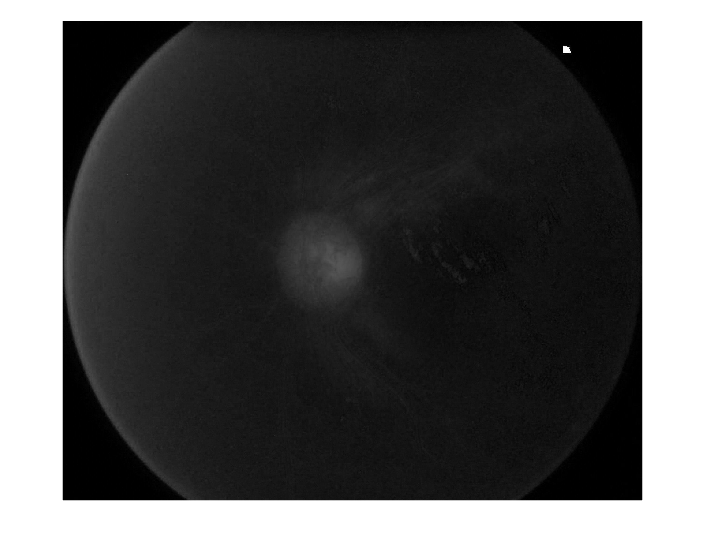

figure;
imshow(RGB(:,:,3),[0*maxB maxB]);

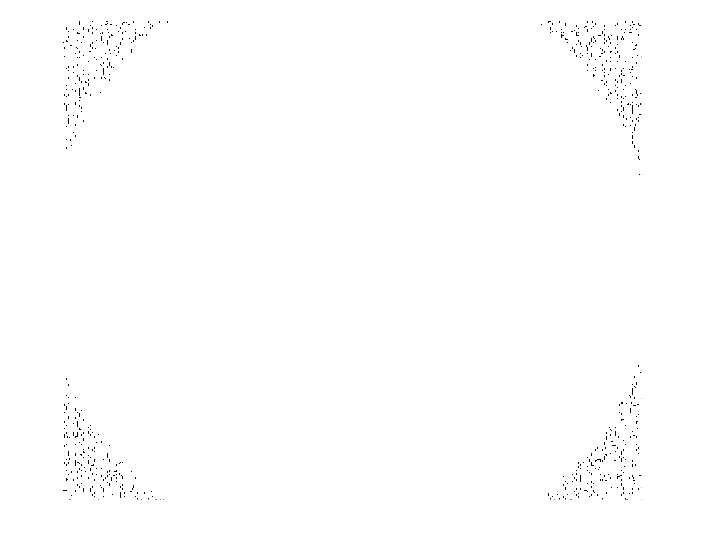

I = double(G);

I=medfilt2(I, [3 3]); 

sobelx= [-1 -2 -1; 0 0 0; 1 2 1]; 
sobely=[-1 0 1;-2 0 2; -1 0 1];
Gx=imfilter(I,sobelx,'conv');
Gy=imfilter(I,sobely,'conv');

sqrtG=sqrt(Gx.^2+Gy.^2); 
Izorrotz=uint8(I+sqrtG);

laplaziar=[0 1 0;1 -4 1;0 1 0];
L=imfilter(I,laplaziar);
Izorrotz2=uint8(I-L);

figure;
imshow(I);

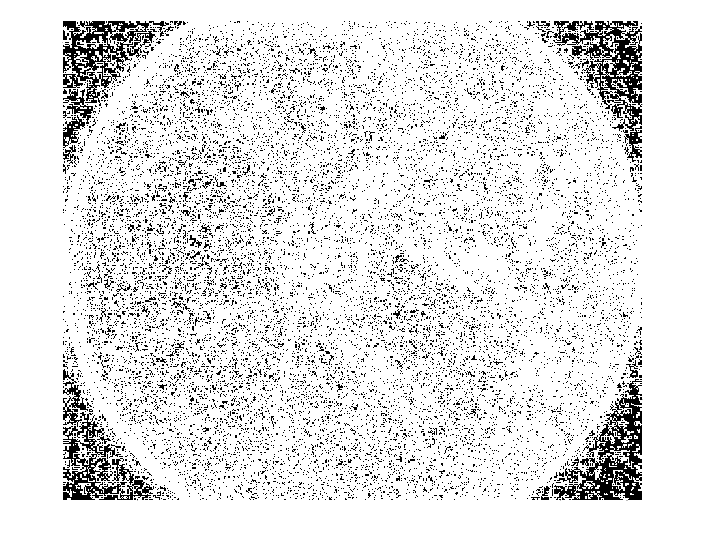


figure;
imshow(sqrtG);

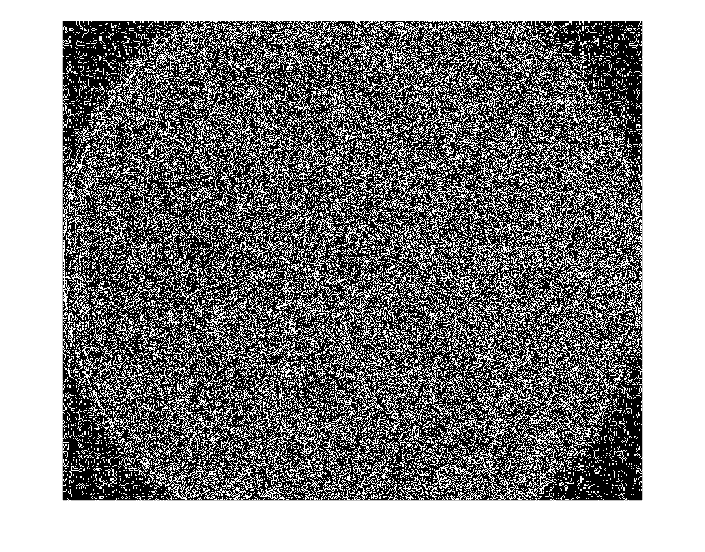


figure;
imshow(L);

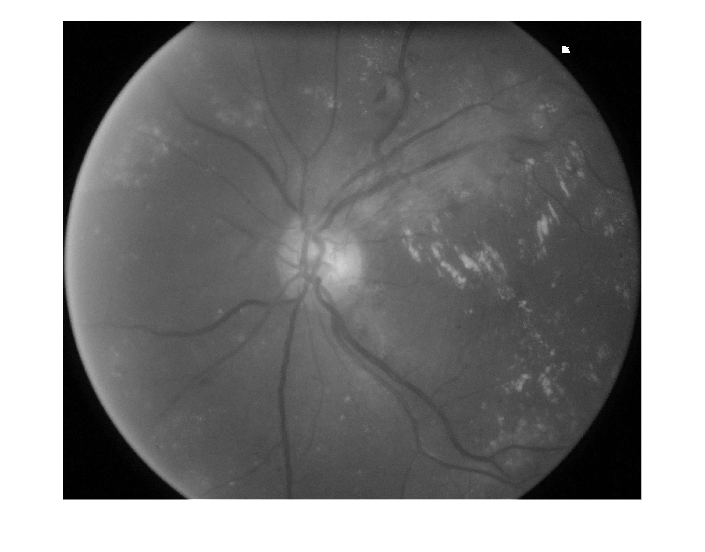


figure;
imshow(Izorrotz2);

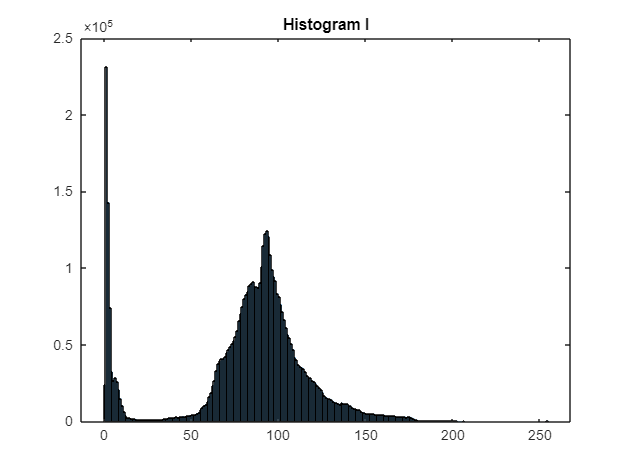

figure;
I=medfilt2(G, [3 3]);
I=uint8(I);
histogram(I);
title('Histogram I');

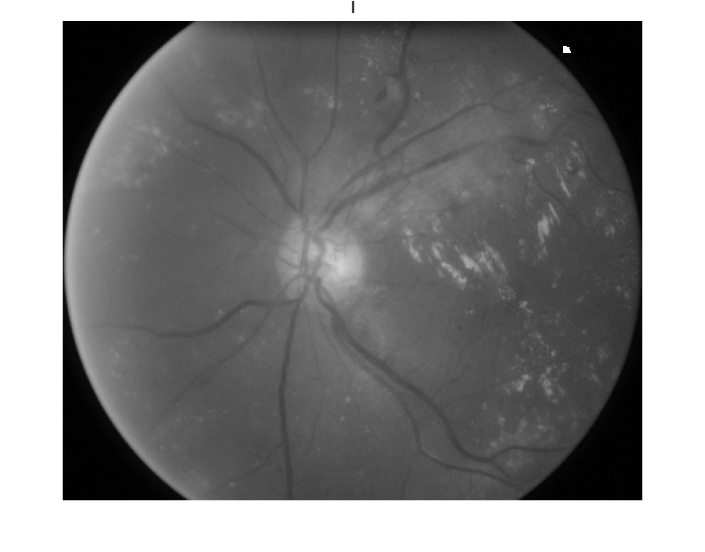


figure;
imshow(I);
title('I');

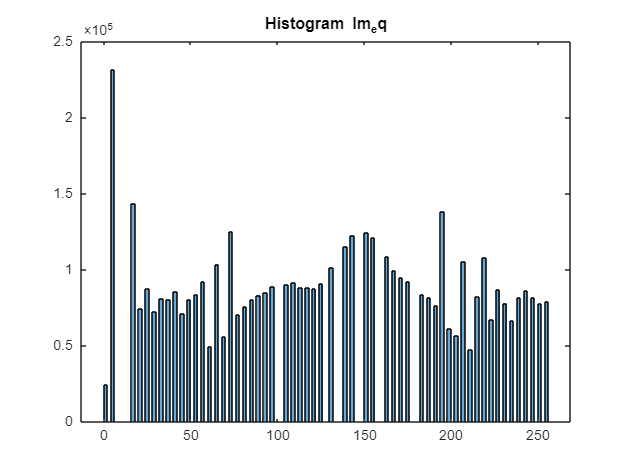


I_eq=histeq(I);
figure;
histogram(I_eq);
title('Histogram Im_eq');

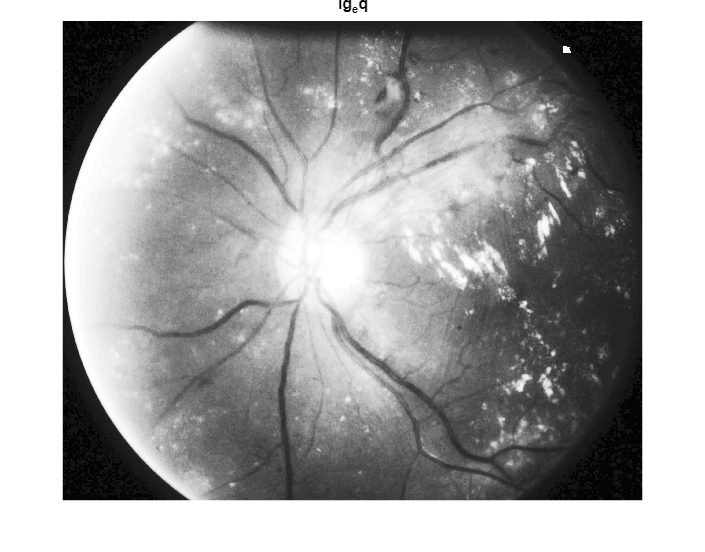


figure;
imshow(I_eq);
title('Ig_eq');

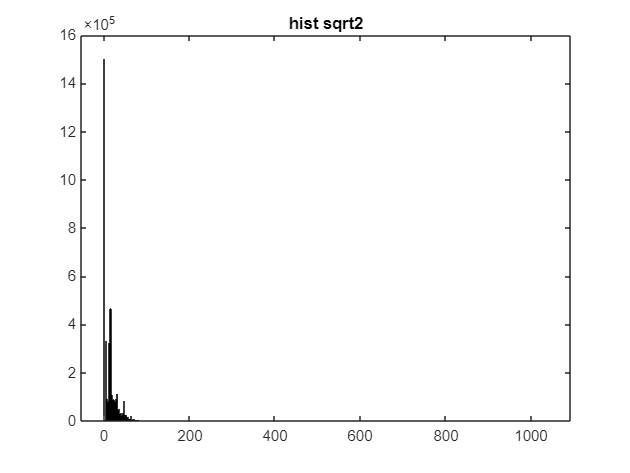


I_eq=double(I_eq);

sobelx= [-1 -2 -1; 0 0 0; 1 2 1]; 
sobely=[-1 0 1;-2 0 2; -1 0 1];
Gx=imfilter(I_eq,sobelx,'conv');
Gy=imfilter(I_eq,sobely,'conv');

sqrtG=sqrt(Gx.^2+Gy.^2); 
figure;
histogram(sqrtG);
title('hist sqrt2');



level = graythresh(sqrtG)

level = 0.4980

max(sqrtG(:))

ans = 1.0404e+03

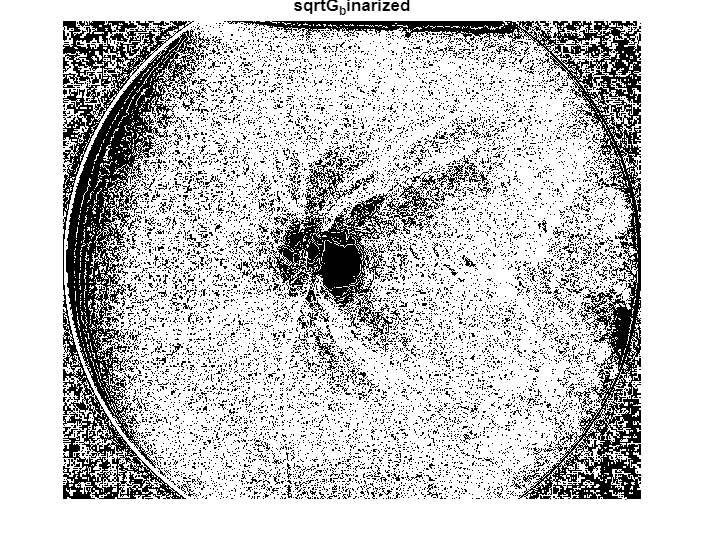

sqrtG_binarized=imbinarize(sqrtG, 1);
figure;
imshow(sqrtG_binarized);
title('sqrtG_binarized');

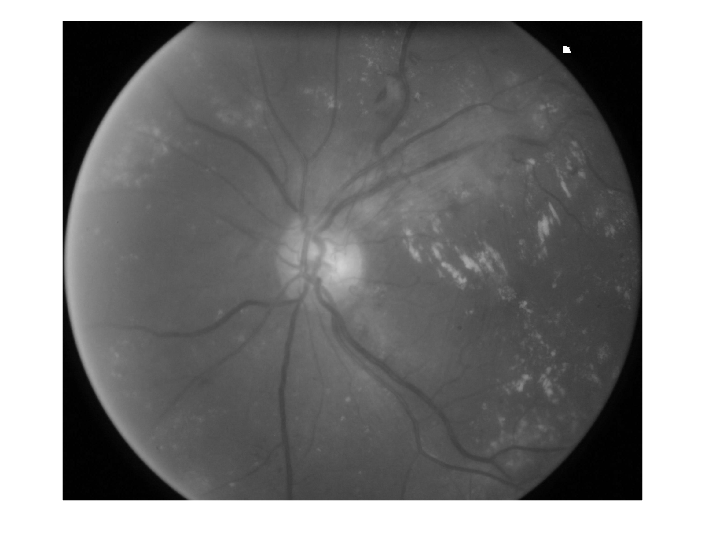



Izorrotz=uint8(I_eq+sqrtG);

laplaziar=[0 1 0;1 -4 1;0 1 0];
L=imfilter(I,laplaziar);
Izorrotz2=uint8(I-L);

figure;
imshow(I);

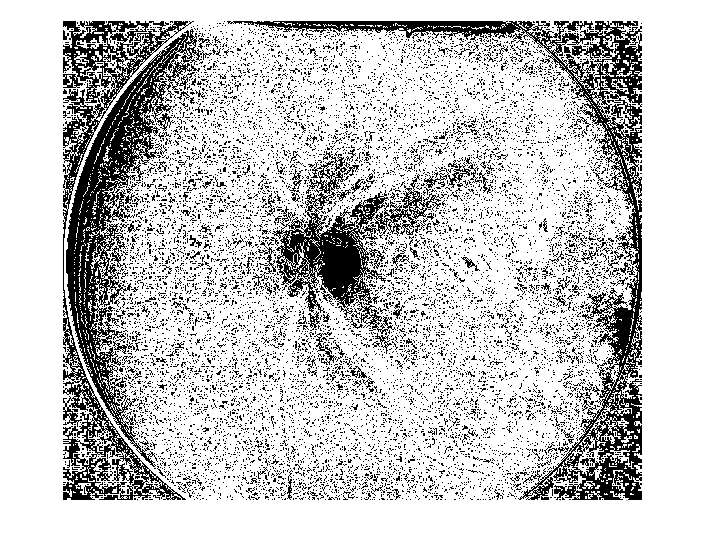


figure;
imshow(sqrtG);

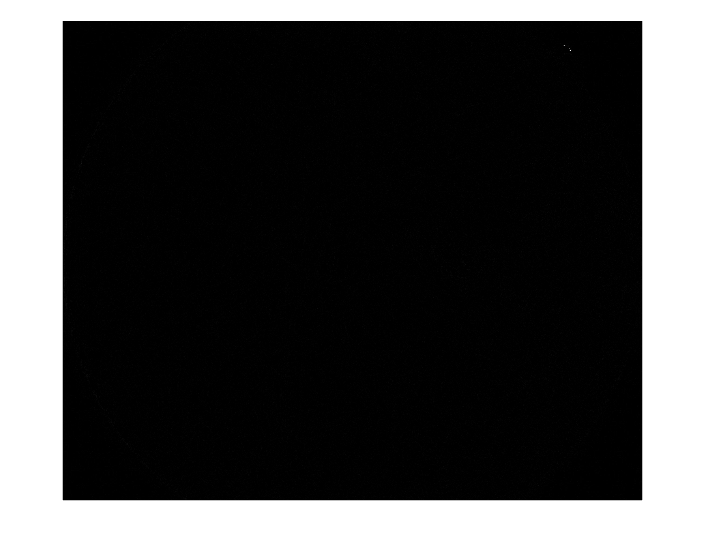


figure;
imshow(L);

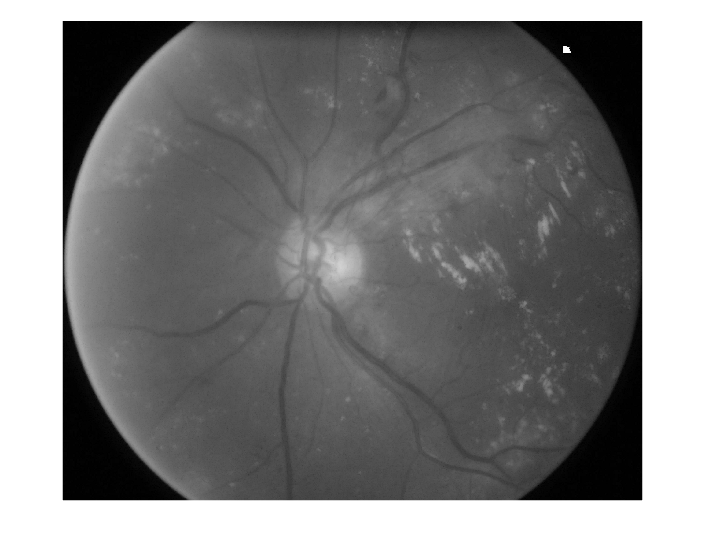


figure;
imshow(Izorrotz2);